# Estructuras de datos: Matrices

La estructura de datos más básica de MATLAB es la matriz. Una matriz es un *arreglo rectangular bidimensional* de elementos de datos dispuestos en filas y columnas.

De forma general se puede pensar que casi todo dentro de MATLAB es una matriz, incluso un solo número se almacena como una matriz.

**Observación**

Un *arreglo* (**array** en inglés) y una *matriz* no son lo mismo. Un arreglo es una colección o grupo de objetos (datos, variables, etc.) que puede tener distintos tipos de datos y puede tener más de 2 dimensiones, mientras que **una matriz es un tipo de arreglo**, más específicamente es un arreglo homogéneo porque únicamente puede contener elementos del mismo tipo, además que una matriz es *bidimensional*: sólo tiene filas y columnas.

**Figura 1.** Tipos de arreglos.

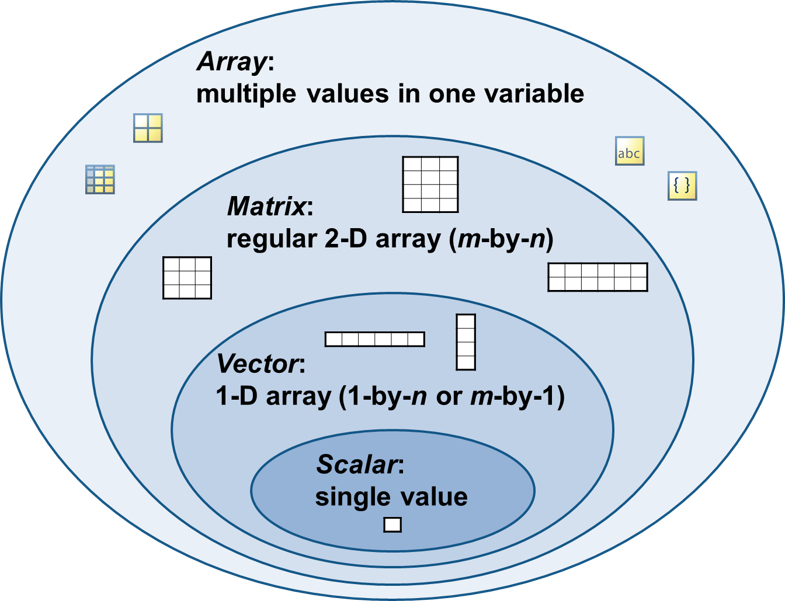

*Tomado de la documentación oficial de MATLAB.*

## Diferencia entre escalar, vector y matriz

Existen 3 conceptos dentro de MATLAB que se debe saber diferenciar bien cuando se trabajan con matrices:

- **Escalar**: matriz de dimensiones $1\times 1$.

- **Vector**: matriz de dimensiones $1\times m$ o $n\times 1$.

- **Matriz**: agrupación de filas y columnas. Es de dimensiones $m\times n$.

### Escalar

Como se mencionó, un escalar posee las dimensiones $1\times 1$.

clear 
x=18;
whos

  Name      Size            Bytes  Class     Attributes

  x         1x1                 8  double              



### Vector

Un vector puede ser de dos tipos: **vector fila** ($1\times m$) o **vector columna** ($n\times 1$). La característica que destaca de cada tipo de vector es que posee o bien una sola fila o bien una sola columna.

Ahora que vamos a definir nuestra primera matriz, es importante conocer lo siguiente:

- **Una matriz se define con corchetes** `[]`

- Para separar las columnas se utiliza la coma `,` o se utiliza al menos un espacio en blanco

- Para separar las filas se utiliza el punto y coma `;` o se utiliza un salto de línea

rowvec=[1,2,3,4,5]

rowvec =      1     2     3     4     5


colvec=[1;2;3;4;5]

colvec =      1
     2
     3
     4
     5


v = [1
    2
    3
    5
    4
    8]

v =      1
     2
     3
     5
     4
     8


**Observación:** Es posible crear un vector columna a través de un vector fila. Esto se realiza añadiendo el operador de transposición (un apóstrofo `'`) al final del vector fila.

colvec2=[1 2 3 4 5 6]'

colvec2 =      1
     2
     3
     4
     5
     6


### Matriz

Para crear una matriz utilizamos tanto `;` como `,` para separar las filas y columnas, respectivamente. Por ejemplo, se tiene la siguiente matriz:


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack$$


Ahora creémosla dentro de MATLAB. Esto se realiza a partir de las filas.

a=[1 2 3;4 5 6;7 8 9]

a =      1     2     3
     4     5     6
     7     8     9


Notemos que primero se crea la fila $\left\lbrack 1\;2\;3\right\rbrack$, luego se crea la fila $\left\lbrack 4\;5\;6\right\rbrack$ y finalmente se crea la fila $\left\lbrack 7\;8\;9\right\rbrack$. Y estas filas están separadas por el punto y coma `;`.

#### Observación

Siempre se debe recordar que una matriz es un arreglo ordenado rectangular (mediante filas y columnas), por ende, si se crea una matriz con una fila de 4 elementos y otra fila de 3 elementos, entonces obtendremos un error.


$$A=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
5 & 6 & 7 & ?
\end{array}\right\rbrack$$


En la forma incorrecta nos falta un elemento para que la matriz esté completa, por eso ocurre el error. En ese espacio $?$ debería ir algún valor para que la matriz se cree sin problemas.

### Matriz vacía

Antes de continuar es menester conocer la matriz vacía. Esta matriz se caracteriza por no tener elementos, atributo que le da su nombre.

Para crear una matriz vacía se utiliza la función `empty`, pero de una manera ligeramente diferente a como hemos trabajado hasta este momento.

Es decir, se debe utilizar la *notación punto* indicando el nombre del tipo de dato (o clase) y luego que se trata de una matriz vacía.

clear 
M=[]


M =

     []



int8.empty


ans =

  0×0 empty int8 matrix



whos

  Name      Size            Bytes  Class     Attributes

  M         0x0                 0  double              
  ans       0x0                 0  int8                



#### Observación

Esta matriz se puede presentar de diferentes formas, no únicamente por dos corchetes sin elementos. Esto dependerá del tipo de dato con el que se esté trabajando, pero es más que suficiente con leer qué tipo de matriz se obtiene. Cuando es una matriz vacía MATLAB suele indicar que se trata de una, además del tipo de matriz.

### Notación científica en matrices

Previamente estudiamos la notación científica dentro de MATLAB, pero ese estudio fue para escalares. Cuando se trata de matrices es ligeramente diferente. La diferencia radica en la visualización de la notación científica de una matriz.

b=[1 2 6 
    4 5 8e10]

b = 1.0e+10 *

    0.0000    0.0000    0.0000
    0.0000    0.0000    8.0000


Por defecto, la notación científica de una matriz siempre se visualizará cuando al menos uno de los elementos de ésta sea muy grande o muy pequeño.

## Crear vectores con el operador dos puntos y la función `linspace`

Es posible crear vectores **linealmente espaciados** con el *operador dos puntos,* `:`,o con la función `linspace`. Sin embargo, se debe diferenciar cuánto utilizar un método u otro.

**Figura  2.** Operador dos puntos VS. Función `linspace`.

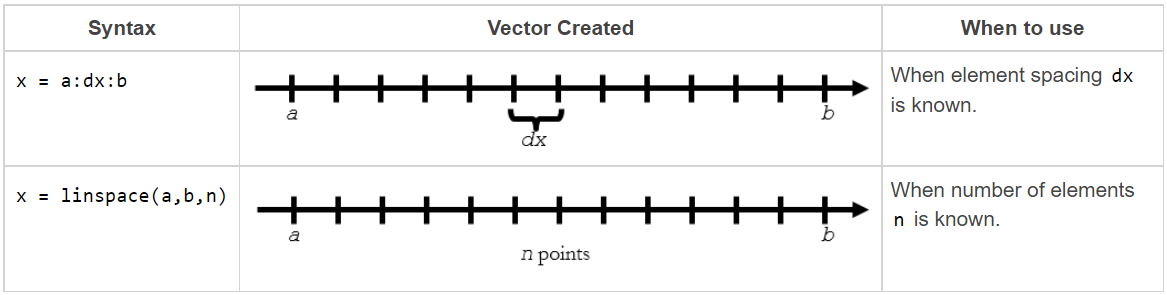

*Tomado de la documentación oficial de MATLAB.*

### Operador dos puntos `:`

El operador dos puntos `:` permite crear vectores linealmente espaciados conociendo:

- el número inicial

- el número final

- el espaciamiento

Lo que se desconoce a priori con el operador dos puntos `:` es el número de elementos.

a=1:9:84

a =      1    10    19    28    37    46    55    64    73    82


#### Ejemplo

La serie de Taylor de la función $e^x$ se define como


$$1+x+\frac{x^2 }{2}+\frac{x^3 }{3!}+\frac{x^4 }{4!}+\frac{x^5 }{5!}+\ldotp \ldotp \ldotp$$


Sumar los primeros 10 elementos de la serie para $x=1$.

**Nota:** Utilizar el siguiente bloque de código, donde únicamente falta definir los términos de la suma.

El código completo, junto con los temas relacionados, se irá explicando a lo largo del curso. Por el momento es necesario enfocarse en la creación de vectores linealmente espaciados.

#### Solución

% Parámetros iniciales.
x = 1;
n = 10;
ValorReal = exp(x);

% Definir los términos de la suma.
Terminos=0:9;
% Crear la varible 'Terminos' que contenga todos los términos de la serie.

% Calcular la serie de Taylor.
Terminos = (x.^Terminos) ./ factorial(Terminos);
ValorAproximacion = sum(Terminos);

% Despliegue de resultados.
fprintf("%.10f", ValorReal)

2.7182818285

fprintf("%.10f", ValorAproximacion)

2.7182815256

#### Observaciones

- Si no se indica el espaciamiento, entonces MATLAB asume que es 1.

a=1:5

a =      1     2     3     4     5


- Si los números generados con el espaciamiento indicado no llega exactamente al número final, entonces tomará el número anterior al número final que sí cumpla con el espaciamiento.

b=4:2:13

b =      4     6     8    10    12


- Si el espaciamiento o numero final es inadecuado, es decir, no hay números entre el número inicial y número final con el espaciamiento indicado, entonces el resultado es la matriz tipo `double` vacía.

b=100:1


b =

  1×0 empty double row vector



### Función `linspace`

La función `linspace` permite crear vectores linealmente espaciados conociendo:

- el número inicial

- el número final

- el número de elementos

Lo que se desconoce a priori con la función `linspace` es el espaciamiento.

y=linspace(0, 10,15)

y =          0    0.7143    1.4286    2.1429    2.8571    3.5714    4.2857    5.0000    5.7143    6.4286    7.1429    7.8571    8.5714    9.2857   10.0000


#### Ejemplo

Visualizar el área bajo la curva de la función $\sqrt{x}$ desde $0$ hasta $2$.

**Nota:** Utilizar el siguiente bloque de código, donde únicamente falta definir los términos de la suma.

El código completo, junto con los temas relacionados, se irá explicando a lo largo del curso. Por el momento es necesario enfocarse en la creación de vectores linealmente espaciados.

#### Solución

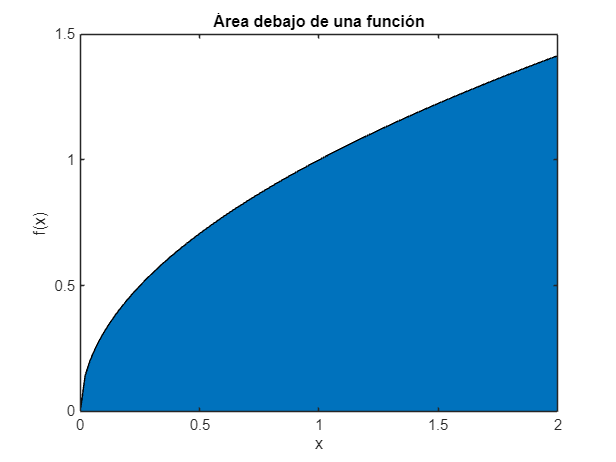

% Establecer los puntos (x, y) de la función.
x=linspace(0,2);
% Definir una variable 'x' con los puntos desde 0 hasta 2.
y = sqrt(x);

% Visualización de la gráfica.
area(x, y)
title("Área debajo de una función")
xlabel("x")
ylabel("f(x)")

#### Observaciones

- Si no se indica el número de elementos, MATLAB que es 100.

a=linspace(5,46)

a =     5.0000    5.4141    5.8283    6.2424    6.6566    7.0707    7.4848    7.8990    8.3131    8.7273    9.1414    9.5556    9.9697   10.3838   10.7980   11.2121   11.6263   12.0404   12.4545   12.8687   13.2828   13.6970   14.1111   14.5253   14.9394   15.3535   15.7677   16.1818   16.5960   17.0101   17.4242   17.8384   18.2525   18.6667   19.0808   19.4949   19.9091   20.3232   20.7374   21.1515   21.5657   21.9798   22.3939   22.8081   23.2222   23.6364   24.0505   24.4646   24.8788   25.2929


- Además, el número final siempre es el último número del vector creado con esta función, a diferencia del operador dos puntos, `:`, donde no necesariamente el número final estará en el vector creado. 

### Función `logspace`

La función `logspace` permite crear vectores logarítmicamente espaciados (en base 10) conociendo:

- la potencia del número inicial

- la potencia del número final

- el número de elementos

Es decir, si se quisieran cierta cantidad de números logarítmicamente espaciados en base 10 con el número inicial ${10}^0$ hasta el número final ${10}^4$, entonces la potencia del número inicial es $0$ y la potencia del número final es $4$.

Lo que se desconoce a priori con la función `logspace` es el espaciamiento.

s=logspace(0,3,8)

s = 1.0e+03 *

    0.0010    0.0027    0.0072    0.0193    0.0518    0.1389    0.3728    1.0000


#### Observación

- Si no se indica el número de elementos, MATLAB que es 50.

g=logspace(0,5)

g = 1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0014    0.0018    0.0022    0.0028    0.0036    0.0045    0.0057    0.0072    0.0091    0.0115    0.0146    0.0184    0.0233    0.0295    0.0373    0.0471    0.0596    0.0754    0.0954    0.1207    0.1526    0.1931    0.2442    0.3089    0.3907    0.4942    0.6251    0.7906    1.0000


### Dimensión predominante en una matriz

La dimensión predominante, o principal, cuando se trabaja con matrices es la columna (o también se le llama dimensión `1`). Luego de la dimensión predominante se encuentra la fila (dimensión secundaria), o dimensión `2`. Si se trabaja con vectores esto no es importante, pero con matrices $m\times n$ sí debe considerarse.

**Figura 3.** Dimensión predominante y dimensión secundaria de una matriz en MATLAB.

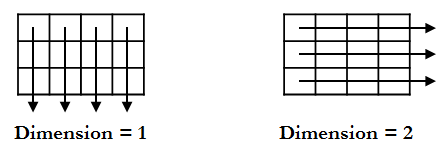

*Tomado de la documentación oficial de MATLAB.*

Por ejemplo, veamos qué ocurre con la función `sum` (suma) cuando se aplica a vectores y matrices.

A=[1 3; 4 8; -9 8;1 0]

A =      1     3
     4     8
    -9     8
     1     0


sum(A) %suma por columna

ans =     -3    19


sum(A,2) %suma por fila 

ans =      4
    12
    -1
     1


    sum(A,"all") % suma de filas y columnas 

ans = 16

#### Observación

Casi todas las funciones dentro de MATLAB trabajarán con las columnas como dimensión predominante y las filas como dimensión secundaria, pero existen ciertas excepciones que trabajarán con las filas como dimensión predominante y las columnas como dimensión secundaria.

Un ejemplo de estas excepciones es la función `circshift`.

#### Observación

Evidentemente se debe considerar esto dependiendo de lo que se requiera realizar, además de si la función utilizada permite o no el cálculo en otras dimensiones.

Por ejemplo, la función `sqrt` (raíz cuadrada) no permite calcular en ninguna dimensión. Esta función directamente aplica la raíz cuadrada a cada elemento de la matriz.

% Ingrese su código aquí :)

Aunque bueno, ¿cuál sería el objetivo de hacer una raíz cuadrada por columna o fila únicamente? Nunca está demás leer un poco de la documentación de una función para conocer las capacidades y limitaciones de ésta.

#### Ejemplo

El archivo "`Tema03_Auxiliar_TemperaturaMediaMensual.mat`" contiene información acerca de la temperatura media mensual (ºC) desde el 2003 hasta el 2006 (columnas) para cada mes del año (filas), de una estación meteorológica.

¿Cuál es el promedio de la temperatura media mensual para cada año? ¿Cuál es la temperatura medial mensual máxima de cada mes a lo largo de los 4 años?

**Nota:** Utilizar las funciones `mean` para el promedio y `max` para el máximo.

#### Solución

% Ingrese su solución aquí :)

## Determinar las dimensiones y el número de elementos

Cuando tenemos una matriz es impotante saber cuáles son sus dimensiones, además de cuántos elementos hay en esta matriz. A continuación se presentan las funciones para este fin.

### Funciones `size` y `length`

La función `size` permite conocer las dimensiones de una matriz.

a=[1 2 3 12; 4 5 6 13; 7 8 9 14]

El primer número representa el número de filas y el segundo número representa el número de columnas.

Por otra parte, la función `length` devuelve el valor de la dimensión más grande.

size(a)
size(size(a))
size(a,1) % numero de filas
size(a,2) %numero de columnas 

La función `length` es especialemente útil cuando se trabajan con vectores, puesto que la dimensión más grande coincide con el número de elementos del vector. No obstante, cuando se quiere conocer cuál es el valor de la dimensión más grande únicamente, también resulta bastante útil.

b=[4 8 56  51 56 516 51 654 654 878 515]

a =      1     2     3    12
     4     5     6    13
     7     8     9    14


length(b) 
length(a) % da la fila o columna con mas elementos 

### Función `numel`

La función `numel` permite conocer el número de elementos dentro de una matriz.

a=[1 2 3 12; 4 5 6 13; 7 8 9 14]

ans =      3     4


numel (a)

ans =      1     2


### Ejemplo

A continuación se muestra un sistema de ecuaciones $3\times 3$,


$$\begin{array}{l}
5x_1 +2x_2 +9x_3 =-10\\
{-2x}_1 +{8x}_2 +{9x}_3 =0\\
{-8x}_1 +{3x}_2 -x_3 =-2
\end{array}$$


Determinar el número de elementos de la matriz de coeficientes sin utilizar la función `numel`.

### Solución

% Ingrese su solución aquí :)

ans = 3

## Concatenar matrices

Teniendo en cuenta las dimensiones de las matrices, es posible concatenar (unir) una o más matrices siempre y cuando el resultado sea una matriz $m\times n$.

**Para concatenar matrices también se utilizan corchetes** `[]`.

**Figura 4.** Concatenación horizontal.

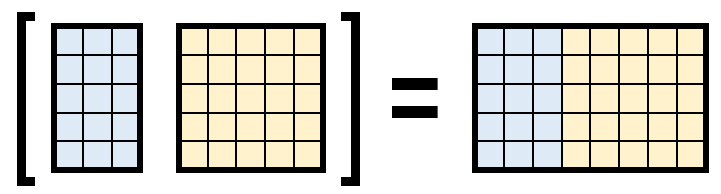

clear

ans = 4

A=[1 2; 3 4 ]
B=[1 2 3; 1 2 3]

b =      4     8    56    51    56   516    51   654   654   878   515


C=[A B]

ans = 11

C=[B A]

ans = 4

**Figura 5.** Concatenación vertical.

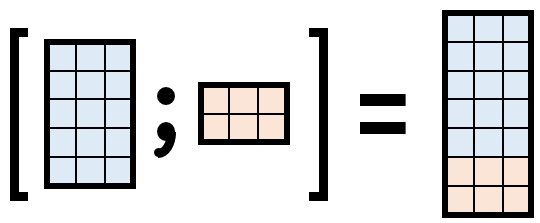

C=[1 2; 1 2]

a =      1     2     3    12
     4     5     6    13
     7     8     9    14


D=[1 2; 3 4 ; 5 6]

ans = 12

E=[C; D]
F=[D;C]

**Figura 6.** Concatenación combinada.

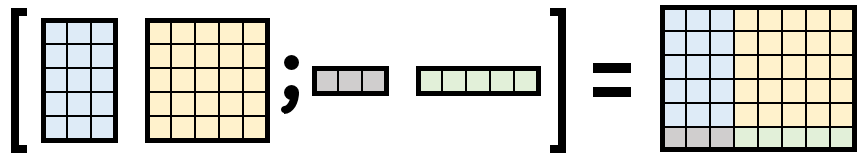

*Todas las figuras fueron tomadas de de la documentación oficial de MATLAB.*

a=[1 2 3; 4 5 6; 7 8 9; 10 11 12]
b=[51 52 53 54 55; 56 57 58 59 60; 61 62 63 64 65; 66 67 68 69 70]
c=[ 100 101 102]
d=[ 205 206 207 208 209]

e=[a b; c d ]

## Redimensionar matrices

Muchas funciones en MATLAB pueden tomar los elementos de una matriz existente y colocarlos en una forma o secuencia diferente. Esto puede ser útil para preprocesar los datos para cálculos posteriores o analizar los datos.

**Figura 7.** Redimensionamiento de una matriz.

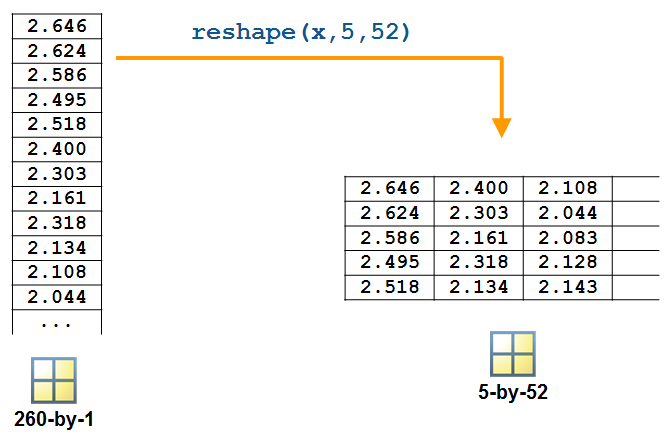

*Tomado de la documentación oficial de MATLAB.*

### Función `reshape`

La función `reshape` permite redimensionar una matriz.

Lo que se debe considerar es que la nueva matriz redimensionada debe contener a todos los elementos de la matriz original. Es decir, el producto de las dimensiones de cualquier matriz redimensionada debe ser igual al producto de las dimensiones de la matriz original.

Por ejemplo, en lugar de tener una matriz $6\times 4$ se podría redimensionar a una matriz $8\times 3$.

A=[4 5 2 1; 4 8 5 4; 1 6 9 4; 4 1 8 7; 1 2 5 7; 1 2 3 9]
B=reshape(A,8,3)

A =      1     2
     3     4


#### Observación

En realidad, si el arreglo es bidimensional (una matriz), es más que suficiente especificarle una dimensión a la función `reshape` para que ésta infiera la otra dimensión. Lo que se debe tener en cuenta es que la dimensión especificada tiene que ser un múltiplo del producto de las dimensiones de la matriz original.

B=reshape(A,[],4)

B =      1     2     3
     1     2     3


### Funciones `flipud` y `fliplr`

La función `flipud` permite voltear una matriz de arriba hacia abajo (**flip** **u**p to **d**own), mientras que la función `fliplr` permite voltear una matriz de izquierda a derecha (**flip** **l**eft to **r**ight).

A=[1 2 3; 4 5 6; 7 8 9; 11 12 13]

C =      1     2     1     2     3
     3     4     1     2     3


fliplr(A)

C =      1     2     3     1     2
     1     2     3     3     4


flipud(A)

### Ejemplo

La función `magic` permite crear una matriz mágica. Una matriz mágica se caracteriza porque la suma de cada una de sus filas, columnas y diagonal principal y secundaria es igual.

Crear una matriz mágica $5\times 5$ y verificar que realmente lo sea.

**Nota:** Utilizar la función `diag` para extraer la diagonal.

### Solución

magica=magic(5)

C =      1     2
     1     2


%verificacion

D =      1     2
     3     4
     5     6


sum(magica,1)

E =      1     2
     1     2
     1     2
     3     4
     5     6


sum(magica,2)

F =      1     2
     3     4
     5     6
     1     2
     1     2


sum(diag(magica))
sum(diag(fliplr(magica)))

## Ordenar matrices

Ordenar los datos en una matriz también es una herramienta valiosa y MATLAB ofrece varios enfoques.

### Función `sort`

La función `sort` permite ordenar los elementos de cada fila o columna de una matriz **por separado** en orden ascendente o descendente.

- Si la matriz es un vector, entonces la función `sort` ordenará los elementos del vector.

- Si la matriz es $m\times n$, entonces la función `sort` tratará las columnas de la matriz como vectores y ordenará cada columna por separado.

Además de esto, también se puede indicar a la función `sort`:

- **La dimensión:** columnas `'1'` (por defecto) o filas `'2'`.

- **La dirección:** `'ascend'` (por defecto) o `'descend'`.

**Figura 8.** Dimensiones de una matriz dentro de una función interna.

*Tomado de la documentación oficial de MATLAB.*

c=[1 0 -5

a =      1     2     3
     4     5     6
     7     8     9
    10    11    12


      -3 2 1

b =     51    52    53    54    55
    56    57    58    59    60
    61    62    63    64    65
    66    67    68    69    70


    8 4 -8]

c =    100   101   102


d =    205   206   207   208   209


d=sort(c)
d=sort(c,"descend")

e =      1     2     3    51    52    53    54    55
     4     5     6    56    57    58    59    60
     7     8     9    61    62    63    64    65
    10    11    12    66    67    68    69    70
   100   101   102   205   206   207   208   209


d=sort(c,2,"descend")

### Función `sortrows`

La función `sortrows` permite ordenar filas o columnas enteras entre sí, en función de una columna de referencia.

Notemos que este es un inconveniente con la anterior función `sort`, puesto que las columnas o filas son tratadas de forma independiente. Si no queremos que se pierda la relación entre fila y columna, es preferible utilizar esta función `sortrows`.

También se puede indicar a la función `sortrows`:

- **La columna de referencia:** depende de cuántas columnas tenga la matriz, pero si no se indica entonces se tomará como referencia la primera columna.

- **La dirección:** `'ascend'` (por defecto) o `'descend'`.

c=[1 0 -5

A =      4     5     2     1
     4     8     5     4
     1     6     9     4
     4     1     8     7
     1     2     5     7
     1     2     3     9


      -3 2 1

B =      4     6     5
     4     1     3
     1     2     1
     4     2     4
     1     2     4
     1     5     7
     5     9     7
     8     8     9


    8 4 -8]
sortrows(c)%toma la 1ra columna para que vaya ascendente y asi mueve los datos de las filas
sortrows(c,2,"descend")

B =      4     5     2     1
     4     8     5     4
     1     6     9     4
     4     1     8     7
     1     2     5     7
     1     2     3     9


d=[1 2;-2 5; 0 8]
dtranspuesta=d'
sortrows(dtranspuesta,2)' % para seleccionar fila envez de columna

### Ejemplo

El archivo "`Tema03_Auxiliar_Supermercado.mat`" contiene una matriz con información de las ventas de un supermercado. La matriz posee cuatro columnas:

- La primera representa el ingreso por cada venta.

- La segunda representa la cantidad de artículos vendidos de cada venta.

- La tercera representa el descuento realizado de cada venta.

- La cuarta representa el beneficio obtenido de cada venta.

¿Cuál es el descuento y beneficio del mayor ingreso de las ventas? ¿Cuál es el ingreso de la venta con mayor beneficio negativo (o pérdida)?

### Solución

clear

A =      1     2     3
     4     5     6
     7     8     9
    11    12    13


load Tema03_Auxiliar_Supermercado.mat

ans =      3     2     1
     6     5     4
     9     8     7
    13    12    11


whos

ans =     11    12    13
     7     8     9
     4     5     6
     1     2     3


disp(SampleSuperstore)

#### Observación

Para odernar por columnas en lugar de por filas, bastaría transponer la matriz para el ordenamiento y luego transponer la matriz ordenada para obtener la matriz original ordenada por columnas.

sortedPerIncomeData= sortrows(SampleSuperstore,"descend")

magica =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


sortedPerNegIncomeData= sortrows(SampleSuperstore,4,"ascend")

## Indexación de matrices

Indexar no es más que acceder a los elementos de una matriz a través de un índice.

En MATLAB existen tres formas principales para acceder a los elementos de la matriz en función de su ubicación (índice) en la matriz. Estos enfoques son la indexación por posición, la indexación lineal (o sencilla) y la indexación lógica.

#### Observación

A continuación se realizarán las explicaciones de cada indexación con matrices numéricas por facilidad. No obstante, la indexación se utiliza con matrices de forma general, por ende, los conceptos que se estudiarán aplican para cualquier tipo de matriz.

### Indexación por posición

Analicemos la siguiente matriz.


$$A=\left\lbrack \begin{array}{ccc}
4_{1,1}  & 8_{1,2}  & 0_{1,3} \\
9_{2,1}  & 2_{2,2}  & 1_{2,3} \\
7_{3,1}  & 5_{3,2}  & 6_{3,3} 
\end{array}\right\rbrack$$


Observemos los índices de cada elemento. Pues bien, se pueden utilizar estos índices (también llamados subíndices) para indexar una matriz por posición. Al igual que la notación matemática, el primer índice indica el número de fila y el segundo índice indica el número de columna.

Es posible indexar:

- **Un único elemento:** Se indican los índices de posición del elemento.

- **Submatrices:** Se indican los índices de las filas y columnas que será extraídas.

- **Filas enteras:** Se indica el índice de la fila o filas, y para las columnas se escribe como índice el operador dos puntos `:`. 

- **Columnas enteras:** Se indica el índice de la columna o columnas, y para las filas se escribe como índice el operador dos puntos `:`.

El operador dos puntos `:` como índice vendría a significar **"todos los elementos"**. También se puede indexar desde un índice hasta otro, indicando un vector linealmente espaciado con índices enteros mayores que cero, en lugar de escribir cada índice manualmente. 

A=[4 8 0; 9 2 1; 7 5 6]

ans =     65    65    65    65    65


A(1,3)

ans =     65
    65
    65
    65
    65


A([1 2], [1 2])

ans = 65

A([1 3],[1 3])

ans = 65

Ahora bien, un detalle a tener en cuenta es que **los índices siempre son números enteros**, matemáticamente hablando. No tendría sentido indexar la fila 1.5 y la columna 2.3, ¿verdad?

Por cierto, ¿cuál sería el resultado del siguiente código?

A(1,:)
A([1 2],:)
A(:,[1 3])

c =      1     0    -5
    -3     2     1
     8     4    -8


B=[ 1 2 3; 5 4 8; 7 9 8; 7 5 3; 6 5 4]
c=B([1:4],:)

d =     -3     0    -8
     1     2    -5
     8     4     1


B(:,:)

d =      8     4     1
     1     2    -5
    -3     0    -8


### Ejemplo

El archivo "`Tema03_Auxiliar_Supermercado.mat`" contiene una matriz con información de las ventas y beneficio de un supermercado. La matriz que contiene el archivo posee cuatro columnas:

- La primera representa el ingreso por cada venta.

- La segunda representa la cantidad de artículos vendidos de cada venta.

- La tercera representa el descuento realizado de cada venta.

- La cuarta representa el beneficio obtenido de cada venta.

Extraer las 1000 ventas con mayor beneficio. Luego, del anterior resultado, extraer el descuento como un vector separado.

### Solución

clear 

d =      1     0    -5
     2     1    -3
     8     4    -8


load Tema03_Auxiliar_Supermercado.mat
whos
sortedData= sortrows(SampleSuperstore,4, "descend")
first1000MostIncomeData = sortedData(1:1000,:)

**Nota:** Utilizando el vector separado que contiene los descuentos de las 1000 ventas con mayor beneficio, se puede utilizar la función `histogram` para generar un histograma con estos datos.

% Añadir la variable 'Descuentos'.
Descuentos=first1000MostIncomeData(:,3)
% Generar un histograma.
histogram(Descuentos)

c =      1     0    -5
    -3     2     1
     8     4    -8


title("Ventas de un supermercado")

ans =     -3     2     1
     1     0    -5
     8     4    -8


subtitle("Descuentos de las 1000 ventas con mayor beneficio")

ans =      8     4    -8
    -3     2     1
     1     0    -5


d =      1     2
    -2     5
     0     8


#### Palabra reservada `end`

La palabra reservada `end` en indexación permite hacer referencia al último elemento de una matriz. En síntesis, es un número que hace referencia al último elemento de una matriz, independientemente del tamaño de la matriz o de si ésta cambia sus dimensiones.

A=[1 2 5 4 ; 1 5 4 8  ; 1 5 7 8]

dtranspuesta =      1    -2     0
     2     5     8


B=[0; 2 ; 3]

ans =      1     2
    -2     5
     0     8


C=[A B]
C(1,4)
C(1,end) % = C(1,5)

Se tendría que seguir la misma lógica para obtener algún elemento empezando desde el final.

#### Convertir una matriz en un vector

En el caso de que se necesite convertir una matriz a un vector, se podría indexar fila a fila, o columna a columna, e ir concatenando estas filas, o columnas, para formar el vector. No obstante, el operador dos puntos `:` facilita este trabajo.

Para convertir una matriz en un vector se debe indexar la matriz únicamente con el operador dos puntos `:`.

% Ingrese su código aquí :)

Pero, ¿de qué forma se transforma la matriz en vector? Esto se detalla con la *indexación lineal*.

### Indexación lineal o sencilla

La indexación lineal, o idexación sencilla, se realiza utilizando un único índice, o también denominado *índice sencillo*. Pero, ¿cómo indexar con un único índice? La siguiente imagen muestra el procedimiento que sigue MATLAB para hacer este tipo de indexación.

**Figura 9.** Proceso de indexación sencilla.

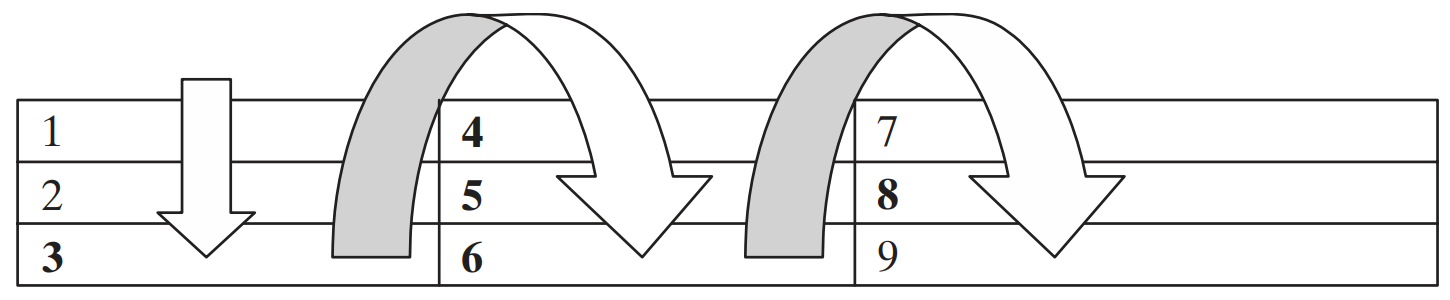

*Tomado de MATLAB para ingenieros de Holly Moore*.

En la anterior figura podemos observar los índices sencillos de una matriz. Es así como funciona el transformar una matriz a un vector `A(:)`, es decir, se apilan las columnas una debajo de otra de derecha a izquierda.

Analicemos la misma matriz anterior con sus índices sencillos:


$$A=\left\lbrack \begin{array}{ccc}
4_1  & 8_4  & 0_7 \\
9_2  & 2_5  & 1_8 \\
7_3  & 5_6  & 6_9 
\end{array}\right\rbrack$$


Con esta indexación únicamente podemos extraer:

- Elementos únicos.

- Vectores fila de elementos indicando los índices sencillos.

- Vectores fila de elementos utilizando el operador dos puntos.

Además, también es posible utilizar la palabra reservada `end` al igual que se hizo con la anterior indexación.

A=[4 8 0; 9 2 1; 7 5 6]
A(2:7)
B=[0 8 4; -5 2 1]

  Name                     Size             Bytes  Class     Attributes

  SampleSuperstore      9994x4             319808  double              



c=-5:.5:-2

   1.0e+04 *

    0.0262    0.0002         0    0.0042
    0.0732    0.0003         0    0.0220
    0.0015    0.0002         0    0.0007
    0.0958    0.0005    0.0000   -0.0383
    0.0022    0.0002    0.0000    0.0003
    0.0049    0.0007         0    0.0014
    0.0007    0.0004         0    0.0002
    0.0907    0.0006    0.0000    0.0091
    0.0019    0.0003    0.0000    0.0006
    0.0115    0.0005         0    0.0034
    0.1706    0.0009    0.0000    0.0085
    0.0911    0.0004    0.0000    0.0068
    0.0016    0.0003    0.0000    0.0005
    0.0408    0.0003    0.0000    0.0133
    0.0069    0.0005    0.0001   -0.0124
    0.0003    0.0003    0.0001   -0.0004
    0.0666    0.0006         0    0.0013
    0.0056    0.0002         0    0.0010
    0.0009    0.0002         0    0.0002
    0.0213    0.0003    0.0000    0.0016
    0.0023    0.0004    0.0000    0.0007
    0.0019    0.0007         0    0.0005
    0.0060    0.0007         0    0.0016
    0.0071    0.0002    0.0000   -0.0001
  

Esta indexación es especialmente útil con vectores en lugar de matrices.

### Ejemplo

El archivo "`Tema03_Auxiliar_SistemaSolar.mat`" contiene el nombre, el radio y la masa de los cuerpos celestes del sistema solar.

Cargar la variable que contiene la masa de los cuerpos y ordenarla de mayor a menor, e indexar los 5 cuerpos celestes con menor masa.

**Nota:** Utilizar la palabra reservada `end`.

### Solución

clear 

sortedPerIncomeData = 1.0e+04 *

    2.2638    0.0006    0.0001   -0.1811
    1.7500    0.0005         0    0.8400
    1.4000    0.0004         0    0.6720
    1.1200    0.0004    0.0000    0.3920
    1.0500    0.0003         0    0.5040
    0.9893    0.0013         0    0.4946
    0.9450    0.0005         0    0.4630
    0.9100    0.0007         0    0.2366
    0.8750    0.0005         0    0.2800
    0.8400    0.0004    0.0000    0.1120


load Tema03_Auxiliar_SistemaSolar.mat masa_kg

sortedPerNegIncomeData = 1.0e+04 *

    0.4500    0.0005    0.0001   -0.6600
    0.8000    0.0004    0.0001   -0.3840
    0.2178    0.0008    0.0001   -0.3702
    0.2550    0.0005    0.0001   -0.3400
    0.1890    0.0005    0.0001   -0.2929
    0.1800    0.0002    0.0001   -0.2640
    0.1525    0.0006    0.0001   -0.2288
    0.4298    0.0013    0.0000   -0.1862
    0.1089    0.0004    0.0001   -0.1851
    2.2638    0.0006    0.0001   -0.1811


whos
disp(masa_kg)
sortMasa_kg= sort(masa_kg,"descend")
sortMasa_kg(end-4:end)

### Indexación lógica

Para el análisis de la indexación lógica se tiene la siguiente figura.

**Figura 10.** Conversión de subíndices a índices.

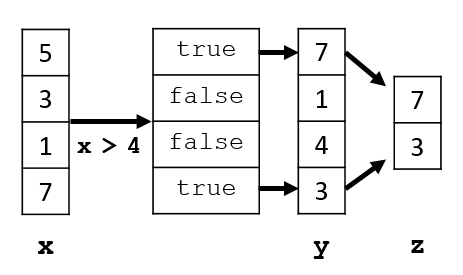

*Tomado de la documentación oficial de MATLAB.*

El uso de valores lógicos es otra forma útil de indexar matrices, especialmente cuando se trabaja con declaraciones condicionales porque se establece una condición y se indexan únicamente los valores que la cumplen.

x=[ 5 3 1 7]>4

A =      4     8     0
     9     2     1
     7     5     6


**Observación:** Los valores lógicos se estudian más adelante, no obstante, para mantener continuidad con el tema de estudio actual se incluye este tipo de indexación. Se recomienda que luego de estudiar los valores lógicos se vuelva a revisar esta indexación lógica si fuera necesario.

### Relación entre los 3 tipos de indexaciones

Existe una función extremadamente poderosa para determinar índices sencillos, índices por posición y los elementos de éstos índices. Además, se puede utilizar una condición lógica para facilitar búsquedas.

#### Función `find`

La función `find` permite determinar índices y valores de elementos distintos de cero. Aunque su potencial va más allá de esto.

A=[1 0 0 -5; 1 2 0 -7]

ans = 0

find(A) % el nuemro de posicion de los elementos que son diferentes a cero 

ans =      4     8
     9     2


find(A,3) % hallar los 3 primeros elementos diferentes a 0

ans =      4     0
     7     6


[row,col]= find(A) % da la posicion de los elementos diferentes a 0 como 1x1 2x1
[row,col,elements]= find(A) % da la posicion y el elemento que hay en esa ubicacion 
[row,col]= find(A>-1)

ans =      4     8     0


#### Ejemplo

El archivo "`Tema03_Auxiliar_SistemaSolar.mat`" contiene el nombre, el radio y la masa de los cuerpos celestes del sistema solar.

Determinar los índices lineales de los radios mayores a 10000 km. Luego, utilizando los índices determinar los nombres de los cuerpos celestes que cumple la condición.

**Nota:** Para la condición se debe utilizar la operación relacional "mayor que" `>`.

#### Solución

clear

ans =      4     8     0
     9     2     1


load Tema03_Auxiliar_SistemaSolar.mat

ans =      4     0
     9     1
     7     6


whos 

B =      1     2     3
     5     4     8
     7     9     8
     7     5     3
     6     5     4


r= 10000000;

c =      1     2     3
     5     4     8
     7     9     8
     7     5     3


idx=find(radio_m > r )

ans =      1     2     3
     5     4     8
     7     9     8
     7     5     3
     6     5     4


nombre_cuerpo(idx)

### Reemplazar elementos de una matriz

Utilizando cualquier tipo de indexación se puede reemplazar elementos de una matriz. Únicamente se indexan los elementos y se asignan los nuevos valores.

A=[1 2 3; 4 5 6; 7 8 9]
A(2,2) =-1
A(1:2,1:2)=[-1 -2 ; -3 -4]

  Name                     Size             Bytes  Class     Attributes

  SampleSuperstore      9994x4             319808  double              



Esto funciona tanto para reemplazar un único elemento o varios elementos. Lo que se debe considerar es que la matriz que se indexa debe ser del mismo tamaño (tener las mismas dimensiones) que la matriz que reemplazará a la matriz indexada.

A(1:2,1:2)=[-1 -2 ; -3 -4; -5 -6]

sortedData = 1.0e+04 *

    1.7500    0.0005         0    0.8400
    1.4000    0.0004         0    0.6720
    1.0500    0.0003         0    0.5040
    0.9893    0.0013         0    0.4946
    0.9450    0.0005         0    0.4630
    1.1200    0.0004    0.0000    0.3920
    0.6355    0.0005         0    0.3177
    0.8750    0.0005         0    0.2800
    0.5400    0.0009         0    0.2592
    0.5444    0.0004         0    0.2504


### Expandir una matriz

Una forma de expandir una matriz es concatenarla con otros elementos o matrices. No obstante, mediante indexación también es posible expandir una matriz.

Se debe indicar un índice fuera de rango de la matriz, es decir, que sea más grande que las dimensiones de la matriz y asignarle un valor o valores. Esto forzará a la matriz a expandirse rellenando los elementos en las posiciones que no se hayan asignado nada con ceros.

Lo que siempre se debe tener en cuenta es que la matriz resultante siempre debe ser consistente, dimensionalmente hablando.

A=[1 2; 3 4]

first1000MostIncomeData = 1.0e+04 *

    1.7500    0.0005         0    0.8400
    1.4000    0.0004         0    0.6720
    1.0500    0.0003         0    0.5040
    0.9893    0.0013         0    0.4946
    0.9450    0.0005         0    0.4630
    1.1200    0.0004    0.0000    0.3920
    0.6355    0.0005         0    0.3177
    0.8750    0.0005         0    0.2800
    0.5400    0.0009         0    0.2592
    0.5444    0.0004         0    0.2504


A(2,3)=-1
A(10,10)=99
A(10,1:10)=1:10

Descuentos =          0
         0
         0
         0
         0
    0.2000
         0
         0
         0
         0


Ahora bien, ¿cuál sería la matriz resultante del siguiente código?

### Eliminar elementos de una matriz

Para eliminar elementos de una matriz se utiliza la matriz vacía `[]`. Basta con utilizar cualquier indexación e indexar los elementos que se desean eliminar y asignarles la matriz vacía.

c=1:.5:5

Esto funciona tanto para eliminar un único elemento o varios elementos. Lo que se debe considerar es que la matriz final debe ser consistente en sus dimensiones.

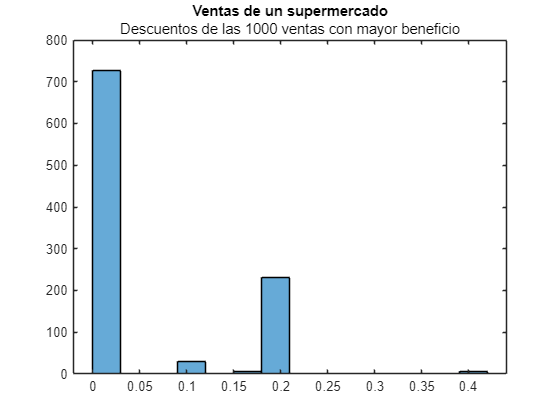

c(3)=[]
c(end-2) = []

A=[1 2; 3 4]
A(10,1:10)=1:10
A(3:end,:)=[]
C = [1 2 3
     4 5 6]


A =      1     2     5     4
     1     5     4     8
     1     5     7     8


% Eliminar varios elementos de la matriz.

B =      0
     2
     3


C(2, [1 2]) = []

C =      1     2     5     4     0
     1     5     4     8     2
     1     5     7     8     3


Por cierto, ¿cuál sería la matriz resultante del siguiente código?

## Matrices especiales

Dentro de MATLAB existen algunas funciones que permiten crear matrices con ciertas características, por lo que se las llaman matrices especiales.

### Función `zeros`

La función `zeros` permite crear una matriz $m\times n$ llena de ceros.

zeros(4,5)

ans = 4

#### Observación

Si a la función `zeros` se le pasa únicamente un argumento, es decir, el valor de una sola dimensión, entonces se creará una matriz cuadrada llena de ceros del orden del argumento indicado.

zeros(5)

ans = 0

### Función `ones`

La función `ones` permite crear una matriz $m\times n$ llena de unos.

ones(8,9)

#### Observación

Si a la función `ones` se le pasa únicamente un argumento, es decir, el valor de una sola dimensión, entonces se creará una matriz cuadrada llena de unos del orden del argumento indicado.

ones(9)

A =      4     8     0
     9     2     1
     7     5     6


### Ejemplo

Crear una matriz que contenga el número $\pi$ en todas sus entradas. ¿Existe más de una forma de hacerlo?

### Solución

zeros(50)+pi

ans =      9     7     8     2     5     0


ones(20,800)* pi

B =      0     8     4
    -5     2     1


### Función `eye`

La función `eye` permite crear una matriz $m\times n$ identidad.

A=[4 5 6 7 8

c =    -5.0000   -4.5000   -4.0000   -3.5000   -3.0000   -2.5000   -2.0000


    4 5 6 8 9
    5 6 7 8 9
    1 2 3 4 5]
eye(8,3)

### Función `diag`

La función `diag` permite crear una matriz diagonal, la cual utilizará el vector ingresado como elementos de la diagonal principal.

A=[1 2 3; 4 5 6 ; 7 8 9]
D=diag(A,-1)

No obstante, si se le indica un segundo argumento a la función `diag`, el parámetro `k`, la función desplazará la diagonal como se muestra en la siguiente figura. 

**Figura 11.** Parámetro $k$ de la función `diag`.

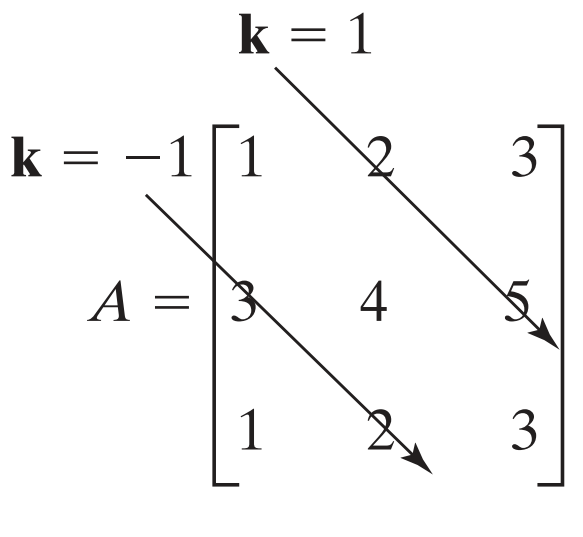

*Tomado de MATLAB para ingenieros de Holly Moore.*

diag(D)

  Name         Size            Bytes  Class     Attributes

  masa_kg      9x1                72  double              



a=[1 5 4 8 2 5  6 4 42 5 ]

   1.0e+30 *

    1.9800
    0.0000
    0.0000
    0.0000
    0.0000
    0.0019
    0.0006
    0.0001
    0.0001



diag(a)

sortMasa_kg = 1.0e+30 *

    1.9800
    0.0019
    0.0006
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000


#### Observación

Si se pasa como argumento a la función `diag` una matriz en lugar de un vector, entonces esta función extraerá la diagonal de esta matriz. También es posible indicar mediante el parámetro `k` qué diagonal se quiere extraer.

% Ingrese su código aquí :)

ans = 1.0e+25 *

    8.6700
    0.5980
    0.4830
    0.0640
    0.0328


x = 1×4 logical array
   1   0   0   1


A =      1     0     0    -5
     1     2     0    -7


ans =      1
     2
     4
     7
     8


ans =      1
     2
     4


row =      1
     2
     2
     1
     2


col =      1
     1
     2
     4
     4


row =      1
     2
     2
     1
     2


col =      1
     1
     2
     4
     4


elements =      1
     1
     2
    -5
    -7


row =      1
     2
     1
     2
     1
     2


col =      1
     1
     2
     2
     3
     3


  Name               Size            Bytes  Class     Attributes

  masa_kg            9x1                72  double              
  nombre_cuerpo      9x1              1042  cell                
  radio_m            9x1                72  double              



idx =      1
     6
     7
     8
     9


ans = 5×1 cell array
    {'Sol'    }
    {'Júpiter'}
    {'Saturno'}
    {'Urano'  }
    {'Neptuno'}


A =      1     2     3
     4     5     6
     7     8     9


A =      1     2     3
     4    -1     6
     7     8     9


A =     -1    -2     3
    -3    -4     6
     7     8     9


Unable to perform assignment because the size of the left side is 2-by-2 and the size of the right side is 3-by-2.

A =      1     2
     3     4


A =      1     2     0
     3     4    -1


A =      1     2     0     0     0     0     0     0     0     0
     3     4    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0    99


A =      1     2     0     0     0     0     0     0     0     0
     3     4    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     1     2     3     4     5     6     7     8     9    10


c =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


c =     1.0000    1.5000    4.5000    5.0000


c =     1.0000    4.5000    5.0000


A =      1     2
     3     4


A =      1     2     0     0     0     0     0     0     0     0
     3     4     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     1     2     3     4     5     6     7     8     9    10


A =      1     2     0     0     0     0     0     0     0     0
     3     4     0     0     0     0     0     0     0     0


C =      1     2     3
     4     5     6


A null assignment can have only one non-colon index.

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


ans =      1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1


ans =      1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1


ans =     3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416   

ans =     3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416   

A =      4     5     6     7     8
     4     5     6     8     9
     5     6     7     8     9
     1     2     3     4     5


ans =      1     0     0
     0     1     0
     0     0     1
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


A =      1     2     3
     4     5     6
     7     8     9


D =      4
     8


ans =      4     0
     0     8


a =      1     5     4     8     2     5     6     4    42     5


ans =      1     0     0     0     0     0     0     0     0     0
     0     5     0     0     0     0     0     0     0     0
     0     0     4     0     0     0     0     0     0     0
     0     0     0     8     0     0     0     0     0     0
     0     0     0     0     2     0     0     0     0     0
     0     0     0     0     0     5     0     0     0     0
     0     0     0     0     0     0     6     0     0     0
     0     0     0     0     0     0     0     4     0     0
     0     0     0     0     0     0     0     0    42     0
     0     0     0     0     0     0     0     0     0     5


## Material adicional

- [Creación, concatenación y expansión de matrices](https://www.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html)

- [Redimensionar y reorganizar matrices](https://www.mathworks.com/help/matlab/math/reshaping-and-rearranging-arrays.html)

- [Crear arreglos de cadenas](https://www.mathworks.com/help/matlab/matlab_prog/create-string-arrays.html)

- [Operaciones lógicas (o booleanas)](https://www.mathworks.com/help/matlab/logical-operations.html)

- [Indexación de arreglos](https://www.mathworks.com/help/matlab/math/array-indexing.html)

- [Encontrar elementos de una matriz que cumplan una condición](https://www.mathworks.com/help/matlab/matlab_prog/find-array-elements-that-meet-a-condition.html)

- [Función `find`](https://www.mathworks.com/help/matlab/ref/find.html)